acc_thigh=out.estimated_acc_thigh.Data(1:3,:,:);
acc_shank=out.estimated_acc.Data(1:3,:,:);
gyro_thigh=out.estimated_gyro_thigh.Data(1:3,:,:);
gyro_shank=out.estimated_gyro.Data(1:3,:,:);


[acc_thigh_x, acc_thigh_y, acc_thigh_z] = deal(squeeze(acc_thigh(1, :, :)), squeeze(acc_thigh(2, :, :)), squeeze(acc_thigh(3, :, :)));
[acc_shank_x, acc_shank_y, acc_shank_z] = deal(squeeze(acc_shank(1, :, :)), squeeze(acc_shank(2, :, :)), squeeze(acc_shank(3, :, :)));
[gyro_thigh_x, gyro_thigh_y, gyro_thigh_z] = deal(squeeze(gyro_thigh(1, :, :)), squeeze(gyro_thigh(2, :, :)), squeeze(gyro_thigh(3, :, :)));
[gyro_shank_x, gyro_shank_y, gyro_shank_z] = deal(squeeze(gyro_shank(1, :, :)), squeeze(gyro_shank(2, :, :)), squeeze(gyro_shank(3, :, :)));

w=2;

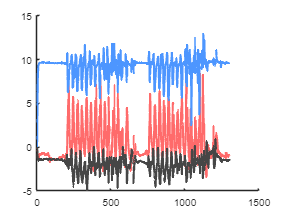

figure;
hold on;
plot(acc_thigh_x, 'Color', [255/255, 107/255, 107/255], 'LineWidth', w);
plot(acc_thigh_y, 'Color', [77/255, 150/255, 255/255], 'LineWidth', w);
plot(acc_thigh_z, 'Color', [70/255, 70/255, 70/255], 'LineWidth', w);
hold off;

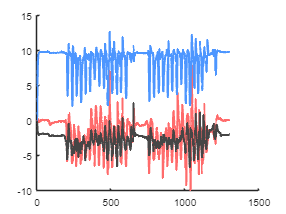

figure;
hold on;
plot(acc_shank_x, 'Color', [255/255, 107/255, 107/255], 'LineWidth', w);
plot(acc_shank_y, 'Color', [77/255, 150/255, 255/255], 'LineWidth', w);
plot(acc_shank_z, 'Color', [70/255, 70/255, 70/255], 'LineWidth', w);
hold off;

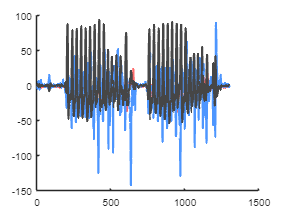

figure;
hold on;
plot(gyro_thigh_x, 'Color', [255/255, 107/255, 107/255], 'LineWidth', w);
plot(gyro_thigh_y, 'Color', [77/255, 150/255, 255/255], 'LineWidth', w);
plot(gyro_thigh_z, 'Color', [70/255, 70/255, 70/255], 'LineWidth', w);
hold off;

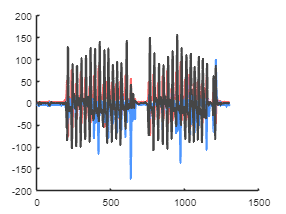

figure;
hold on;
plot(gyro_shank_x, 'Color', [255/255, 107/255, 107/255], 'LineWidth', w);
plot(gyro_shank_y, 'Color', [77/255, 150/255, 255/255], 'LineWidth', w);
plot(gyro_shank_z, 'Color', [70/255, 70/255, 70/255], 'LineWidth', w);
hold off

gyro_thigh_z_interp=interp1(1:length(gyro_shank_z),gyro_shank_z, linspace(1,length(gyro_shank_z),10000),'linear');

point=find(diff(sign(gyro_thigh_z_interp))~=0);
disp(point);

           1          59         102         195         218         306         311         351         356         399         437         510         528         583         691        1195        1247        1341        1376        1422        1438        1447        1464        1482        1585        1640        1833        1955        2060        2120        2154        2200        2291        2450        2525        2602        2621        2669        2754        2818        2978        3056        3226        3300        3471        3539        3679        3790        3915        4001        4137        4220        4358        4451        4623        4694        4845        4897        4924        5026        5057        5228        5347        5676        5687        5701        5834        5900        6073        6219        6316        6380        6384        6442        6550        6611        6628        6694        6787        6849        6884        6924        7011    

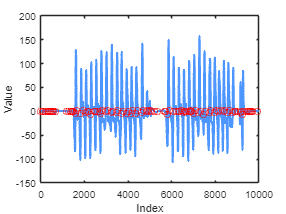


figure;
plot(gyro_thigh_z_interp, 'Color', [77/255, 150/255, 255/255], 'LineWidth', w);
hold on;
plot(point, gyro_thigh_z_interp(point), 'ro');
xlabel('Index');
ylabel('Value');

time=out.Time.Data;
time=interp1(1:length(time),time, linspace(1,length(time),10000),'linear');
a=[time(5900),time(6884),time(7804),time(8672)]

a = 1.0e+03 *

    0.9908    1.0033    1.0150    1.0261


[mean(max(exo_no.LG)),std(max(exo_no.LG))]

ans =     8.8806    3.9483


[mean(max(exo_off.LG)),std(max(exo_off.LG))]

ans =     6.7438    2.0753


[mean(max(exo_on.LG)),std(max(exo_on.LG))]

ans =    27.1291    5.7083




[mean(max(exo_no.IC)),std(max(exo_no.IC))]

ans =     7.9199    1.4816


[mean(max(exo_off.IC)),std(max(exo_off.IC))]

ans =    25.9982    2.7882


[mean(max(exo_on.IC)),std(max(exo_on.IC))]

ans =    21.0649    2.0830



[mean(max(exo_no.DC)),std(max(exo_no.DC))]

ans =     9.1403    2.2682


[mean(max(exo_off.DC)),std(max(exo_off.DC))]

ans =    25.0832    3.6286


[mean(max(exo_on.DC)),std(max(exo_on.DC))]

ans =    25.6522    5.1586




std(mean(exo_no.LG, 2)-mean(exo_off.LG, 2))

ans = 7.0177